# Introducció al Matlab

## Operacions amb vectors

% Creació de vectors
x = [1 2 3 4 5] % vector fila

x =      1     2     3     4     5


y = [5; 6; 7; 8; 9;] % vector columna

y =      5
     6
     7
     8
     9


x = x' % trasposada

x =      1
     2
     3
     4
     5


z = 1:1:10 % progressió inici:pas:fi

z =      1     2     3     4     5     6     7     8     9    10


x(1) %primer element de l'array !Els vactors, matrius, etc. comencen amb índex 1

ans = 1

q = zeros([1 5]) %omplir vectors amb zeros

q =      0     0     0     0     0


k = ones([5 1]) %omplir vectors amb uns

k =      1
     1
     1
     1
     1


x = x'

x =      1     2     3     4     5


x*y % producte escalar

ans = 115

norm(x) % longitud del vector (mòdul del vector)

ans = 7.4162

sqrt(x*x') % mòdul del vector (mètode 2)

ans = 7.4162


q = rand([1 1000000]); % creació columna de un milió de valors aleatoris entre 0 i 1
tic %inici cronòmetre
q*q' % mòdul vector

ans = 3.3347e+05

toc % fi cronòmetre

Elapsed time is 0.003409 seconds.


## Operacions amb matrius

X = rand([10 10]) %generar matriu 10x10 amb valors aleatòris entre 0 i 1

X =     0.5225    0.7050    0.7573    0.0444    0.8796    0.0832    0.9706    0.8879    0.9825    0.4632
    0.9798    0.1704    0.2909    0.0429    0.3654    0.1056    0.6497    0.4292    0.7580    0.3337
    0.1265    0.9831    0.6644    0.3009    0.3317    0.0078    0.2011    0.8968    0.8721    0.3296
    0.4956    0.0877    0.7921    0.1860    0.4749    0.5098    0.0153    0.3499    0.6189    0.2554
    0.3198    0.5964    0.6100    0.1056    0.0804    0.3397    0.0808    0.1900    0.8296    0.1256
    0.0777    0.6758    0.6983    0.9616    0.8942    0.2328    0.3758    0.8412    0.7797    0.5116
    0.2149    0.1511    0.5916    0.6808    0.3805    0.2559    0.3372    0.9680    0.2767    0.8456
    0.8099    0.6374    0.2069    0.2595    0.5242    0.6971    0.1301    0.5056    0.3621    0.0321
    0.2319    0.6190    0.1755    0.2289    0.7591    0.1790    0.3989    0.5474    0.0754    0.6353
    0.8598    0.2733    0.8702    0.2932    0.8579    0.9757    0.0863    0.0366    0.9

X(2, 3) % valor de fila 2 columna 3 !Al revés que a mates

ans = 0.2909

s = size(X) % mida de matriu - vector on et diu la mida de cada dimensió

s =     10    10


files = s(1) % número de files

files = 10

columnes = s(2) % número de columnes

columnes = 10

ndims(X) % dimensió de la matriu

ans = 2

Z = [X X] % Concatenació de matrius, en aquest cas 10 x 20

Z =     0.5225    0.7050    0.7573    0.0444    0.8796    0.0832    0.9706    0.8879    0.9825    0.4632    0.5225    0.7050    0.7573    0.0444    0.8796    0.0832    0.9706    0.8879    0.9825    0.4632
    0.9798    0.1704    0.2909    0.0429    0.3654    0.1056    0.6497    0.4292    0.7580    0.3337    0.9798    0.1704    0.2909    0.0429    0.3654    0.1056    0.6497    0.4292    0.7580    0.3337
    0.1265    0.9831    0.6644    0.3009    0.3317    0.0078    0.2011    0.8968    0.8721    0.3296    0.1265    0.9831    0.6644    0.3009    0.3317    0.0078    0.2011    0.8968    0.8721    0.3296
    0.4956    0.0877    0.7921    0.1860    0.4749    0.5098    0.0153    0.3499    0.6189    0.2554    0.4956    0.0877    0.7921    0.1860    0.4749    0.5098    0.0153    0.3499    0.6189    0.2554
    0.3198    0.5964    0.6100    0.1056    0.0804    0.3397    0.0808    0.1900    0.8296    0.1256    0.3198    0.5964    0.6100    0.1056    0.0804    0.3397    0.0808    0.1900    0.8296  

Z = [X; X] % Concatenació en columa

Z =     0.5225    0.7050    0.7573    0.0444    0.8796    0.0832    0.9706    0.8879    0.9825    0.4632
    0.9798    0.1704    0.2909    0.0429    0.3654    0.1056    0.6497    0.4292    0.7580    0.3337
    0.1265    0.9831    0.6644    0.3009    0.3317    0.0078    0.2011    0.8968    0.8721    0.3296
    0.4956    0.0877    0.7921    0.1860    0.4749    0.5098    0.0153    0.3499    0.6189    0.2554
    0.3198    0.5964    0.6100    0.1056    0.0804    0.3397    0.0808    0.1900    0.8296    0.1256
    0.0777    0.6758    0.6983    0.9616    0.8942    0.2328    0.3758    0.8412    0.7797    0.5116
    0.2149    0.1511    0.5916    0.6808    0.3805    0.2559    0.3372    0.9680    0.2767    0.8456
    0.8099    0.6374    0.2069    0.2595    0.5242    0.6971    0.1301    0.5056    0.3621    0.0321
    0.2319    0.6190    0.1755    0.2289    0.7591    0.1790    0.3989    0.5474    0.0754    0.6353
    0.8598    0.2733    0.8702    0.2932    0.8579    0.9757    0.0863    0.0366    0.9

Z = [X X; X X] % Concatenació en quadrat, 20x20

Z =     0.5225    0.7050    0.7573    0.0444    0.8796    0.0832    0.9706    0.8879    0.9825    0.4632    0.5225    0.7050    0.7573    0.0444    0.8796    0.0832    0.9706    0.8879    0.9825    0.4632
    0.9798    0.1704    0.2909    0.0429    0.3654    0.1056    0.6497    0.4292    0.7580    0.3337    0.9798    0.1704    0.2909    0.0429    0.3654    0.1056    0.6497    0.4292    0.7580    0.3337
    0.1265    0.9831    0.6644    0.3009    0.3317    0.0078    0.2011    0.8968    0.8721    0.3296    0.1265    0.9831    0.6644    0.3009    0.3317    0.0078    0.2011    0.8968    0.8721    0.3296
    0.4956    0.0877    0.7921    0.1860    0.4749    0.5098    0.0153    0.3499    0.6189    0.2554    0.4956    0.0877    0.7921    0.1860    0.4749    0.5098    0.0153    0.3499    0.6189    0.2554
    0.3198    0.5964    0.6100    0.1056    0.0804    0.3397    0.0808    0.1900    0.8296    0.1256    0.3198    0.5964    0.6100    0.1056    0.0804    0.3397    0.0808    0.1900    0.8296  

Z(1, 1) = 0 % Assiganció d'un valor de la matriu

Z =          0    0.7050    0.7573    0.0444    0.8796    0.0832    0.9706    0.8879    0.9825    0.4632    0.5225    0.7050    0.7573    0.0444    0.8796    0.0832    0.9706    0.8879    0.9825    0.4632
    0.9798    0.1704    0.2909    0.0429    0.3654    0.1056    0.6497    0.4292    0.7580    0.3337    0.9798    0.1704    0.2909    0.0429    0.3654    0.1056    0.6497    0.4292    0.7580    0.3337
    0.1265    0.9831    0.6644    0.3009    0.3317    0.0078    0.2011    0.8968    0.8721    0.3296    0.1265    0.9831    0.6644    0.3009    0.3317    0.0078    0.2011    0.8968    0.8721    0.3296
    0.4956    0.0877    0.7921    0.1860    0.4749    0.5098    0.0153    0.3499    0.6189    0.2554    0.4956    0.0877    0.7921    0.1860    0.4749    0.5098    0.0153    0.3499    0.6189    0.2554
    0.3198    0.5964    0.6100    0.1056    0.0804    0.3397    0.0808    0.1900    0.8296    0.1256    0.3198    0.5964    0.6100    0.1056    0.0804    0.3397    0.0808    0.1900    0.8296  

v = Z(:) % Transformar matriu a vector

v =          0
    0.9798
    0.1265
    0.4956
    0.3198
    0.0777
    0.2149
    0.8099
    0.2319
    0.8598


Z(Z < 0.5) = 0 % tots els valors menors a 0.5 posar-los a 0

Z =          0    0.7050    0.7573         0    0.8796         0    0.9706    0.8879    0.9825         0    0.5225    0.7050    0.7573         0    0.8796         0    0.9706    0.8879    0.9825         0
    0.9798         0         0         0         0         0    0.6497         0    0.7580         0    0.9798         0         0         0         0         0    0.6497         0    0.7580         0
         0    0.9831    0.6644         0         0         0         0    0.8968    0.8721         0         0    0.9831    0.6644         0         0         0         0    0.8968    0.8721         0
         0         0    0.7921         0         0    0.5098         0         0    0.6189         0         0         0    0.7921         0         0    0.5098         0         0    0.6189         0
         0    0.5964    0.6100         0         0         0         0         0    0.8296         0         0    0.5964    0.6100         0         0         0         0         0    0.8296  

Z(Z ~= 0) = 1 % tots els valors diferents a 0, posar-los a 1

Z =      0     1     1     0     1     0     1     1     1     0     1     1     1     0     1     0     1     1     1     0
     1     0     0     0     0     0     1     0     1     0     1     0     0     0     0     0     1     0     1     0
     0     1     1     0     0     0     0     1     1     0     0     1     1     0     0     0     0     1     1     0
     0     0     1     0     0     1     0     0     1     0     0     0     1     0     0     1     0     0     1     0
     0     1     1     0     0     0     0     0     1     0     0     1     1     0     0     0     0     0     1     0
     0     1     1     1     1     0     0     1     1     1     0     1     1     1     1     0     0     1     1     1
     0     0     1     1     0     0     0     1     0     1     0     0     1     1     0     0     0     1     0     1
     1     1     0     0     1     1     0     1     0     0     1     1     0     0     1     1     0     1     0     0
     0     1     0     0    

%eliminar files/columnes
Z(1, :) = [] % eliminar primera fila - primera fila, tots els elements de la columna

Z =      1     0     0     0     0     0     1     0     1     0     1     0     0     0     0     0     1     0     1     0
     0     1     1     0     0     0     0     1     1     0     0     1     1     0     0     0     0     1     1     0
     0     0     1     0     0     1     0     0     1     0     0     0     1     0     0     1     0     0     1     0
     0     1     1     0     0     0     0     0     1     0     0     1     1     0     0     0     0     0     1     0
     0     1     1     1     1     0     0     1     1     1     0     1     1     1     1     0     0     1     1     1
     0     0     1     1     0     0     0     1     0     1     0     0     1     1     0     0     0     1     0     1
     1     1     0     0     1     1     0     1     0     0     1     1     0     0     1     1     0     1     0     0
     0     1     0     0     1     0     0     1     0     1     0     1     0     0     1     0     0     1     0     1
     1     0     1     0    

Z(:, 1) = [] % eliminar primera columna

Z =      0     0     0     0     0     1     0     1     0     1     0     0     0     0     0     1     0     1     0
     1     1     0     0     0     0     1     1     0     0     1     1     0     0     0     0     1     1     0
     0     1     0     0     1     0     0     1     0     0     0     1     0     0     1     0     0     1     0
     1     1     0     0     0     0     0     1     0     0     1     1     0     0     0     0     0     1     0
     1     1     1     1     0     0     1     1     1     0     1     1     1     1     0     0     1     1     1
     0     1     1     0     0     0     1     0     1     0     0     1     1     0     0     0     1     0     1
     1     0     0     1     1     0     1     0     0     1     1     0     0     1     1     0     1     0     0
     1     0     0     1     0     0     1     0     1     0     1     0     0     1     0     0     1     0     1
     0     1     0     1     1     0     0     1     1     1     0     1    


B = Z(10:end, 11:end) %Agafem la submatriu de la fila 10 al final, i de la columna 11 al final

B =      1     1     0     1     0     1     1     1     0
     0     0     0     0     0     1     0     1     0
     1     1     0     0     0     0     1     1     0
     0     1     0     0     1     0     0     1     0
     1     1     0     0     0     0     0     1     0
     1     1     1     1     0     0     1     1     1
     0     1     1     0     0     0     1     0     1
     1     0     0     1     1     0     1     0     0
     1     0     0     1     0     0     1     0     1
     0     1     0     1     1     0     0     1     1


## Plots

x = 1:1:100

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y = sqrt(x) % arrel quadrada component a component

y =     1.0000    1.4142    1.7321    2.0000    2.2361    2.4495    2.6458    2.8284    3.0000    3.1623    3.3166    3.4641    3.6056    3.7417    3.8730    4.0000    4.1231    4.2426    4.3589    4.4721    4.5826    4.6904    4.7958    4.8990    5.0000    5.0990    5.1962    5.2915    5.3852    5.4772    5.5678    5.6569    5.7446    5.8310    5.9161    6.0000    6.0828    6.1644    6.2450    6.3246    6.4031    6.4807    6.5574    6.6332    6.7082    6.7823    6.8557    6.9282    7.0000    7.0711


hold on % tots els gràfics es mostraran overlaped
plot(x, y) % mostrar gràfic
z = x.*x/1000 % multiplicació component a component

z =     0.0010    0.0040    0.0090    0.0160    0.0250    0.0360    0.0490    0.0640    0.0810    0.1000    0.1210    0.1440    0.1690    0.1960    0.2250    0.2560    0.2890    0.3240    0.3610    0.4000    0.4410    0.4840    0.5290    0.5760    0.6250    0.6760    0.7290    0.7840    0.8410    0.9000    0.9610    1.0240    1.0890    1.1560    1.2250    1.2960    1.3690    1.4440    1.5210    1.6000    1.6810    1.7640    1.8490    1.9360    2.0250    2.1160    2.2090    2.3040    2.4010    2.5000


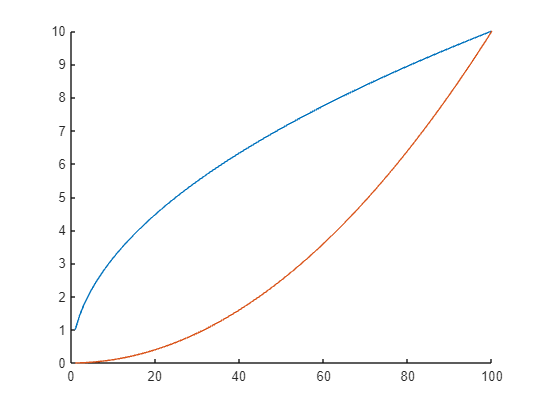

plot (x, z)
hold off % ja no es mostraran les gràfiques overlapped

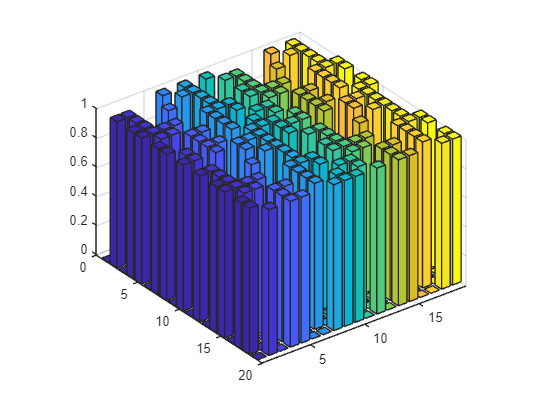

bar3(Z) % diagrama de barres en 3D

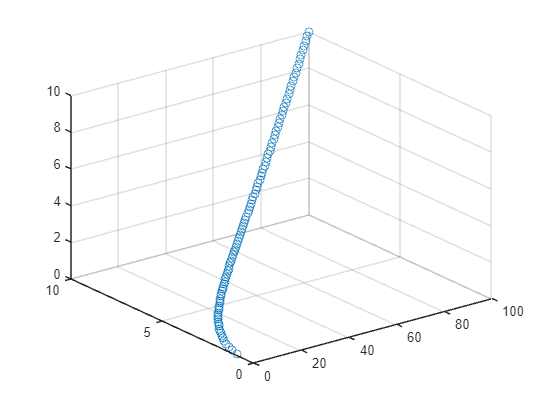

scatter3(x, y, z, 'o') % scatterplot en 3D on cada punt es representa amb 'o'

## Funcions bàsiques

m = max(Z) % retorna el valor màxim de cada columna

m =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


m = max(max(Z)) % retorna el valor màxim de la matriu

m = 1

m = min(min(Z)) % retorna el valor mínim

m = 0

s = sum(Z) % suma totes les columnes

s =     11    13     4     9     6     3    11    13     8     7    11    13     4     9     6     3    11    13     8


s = sum(sum(Z)) % suma tots els valors

s = 163

## Funcions pròpies

c = myFunction(x)

c =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100
     3     6     9    12    15    18    21    24    27    30    33    36    39    42    45    48    51    54    57    60    63    66    69    72    75    78    81    84    87    90    93    96    99   102   105   108   111   114   117   120   123   126   129   132   135   138   141   144   147   150
     4     8    12    16    20    24    28    32    36    40    44    48    52    56    60   